# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 28-Apr-2022 17:05:15

## Setup the Import Options

opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = [12, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Run", "High", "Counts", "Elapsed", "VarName5", "VarName6"];
opts.VariableTypes = ["double", "double", "double", "double", "datetime", "string"];
opts = setvaropts(opts, 5, "InputFormat", "MM/dd/yy hh:mm:ss aa");
opts = setvaropts(opts, 6, "WhitespaceRule", "preserve");
opts = setvaropts(opts, 6, "EmptyFieldRule", "auto");
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
ISLPo2100 = readtable("D:\sarahDoron\ISL_Po-210_0.1uCi_8Nov2021_filtered.tsv", opts)

ISLPo2100 = 16×6 table
    Run    High    Counts    Elapsed          VarName5          VarName6
    ___    ____    ______    _______    ____________________    ________

     1     1120      911       10       04/28/22 04:05:56 PM       ""   
     2     1120        5       10       04/28/22 04:06:28 PM       ""   
     6     1120       15       10       04/28/22 04:19:31 PM       ""   
     7     1120       11       10       04/28/22 04:21:13 PM       ""   
     8     1120       91       10       04/28/22 04:26:41 PM       ""   
     9     1120      135       10       04/28/22 04:27:37 PM       ""   
    10     1120       66       10       04/28/22 04:29:38 PM       ""   
    11     1120       40       10       04/28/22 04:31:38 PM       ""   
    12     1120        7       10       04

clear opts

## Plot stuff

distances = [
    0,
    0.665,
    0.665+0.290,
    0.665+0.250,
    0.665+0.462,
    0.665+0.510,
    0.665+0.290 + 0.070,
    0.665+0.290 + 0.012,
    0.665+0.150 + 0.062,
    0.665+0.216,
    0.665+0.216 + 0.062,
    0.665+1.150,
    0.665+0.902,
    0.665+0.608,
    0.665+0.810,
    0.665+0.708
] % cm;

distances =          0
    0.6650
    0.9550
    0.9150
    1.1270
    1.1750
    1.0250
    0.9670
    0.8770
    0.8810


ISLPo2100.Counts

ans =    911
     5
    15
    11
    91
   135
    66
    40
     7
     3


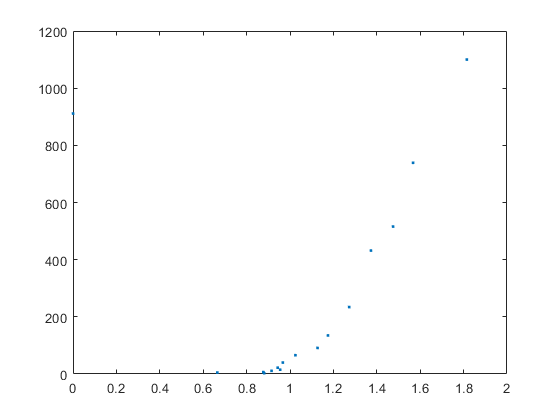

plot(distances, ISLPo2100.Counts, '.')